Lab 6: CDMA Encoding

Part 1

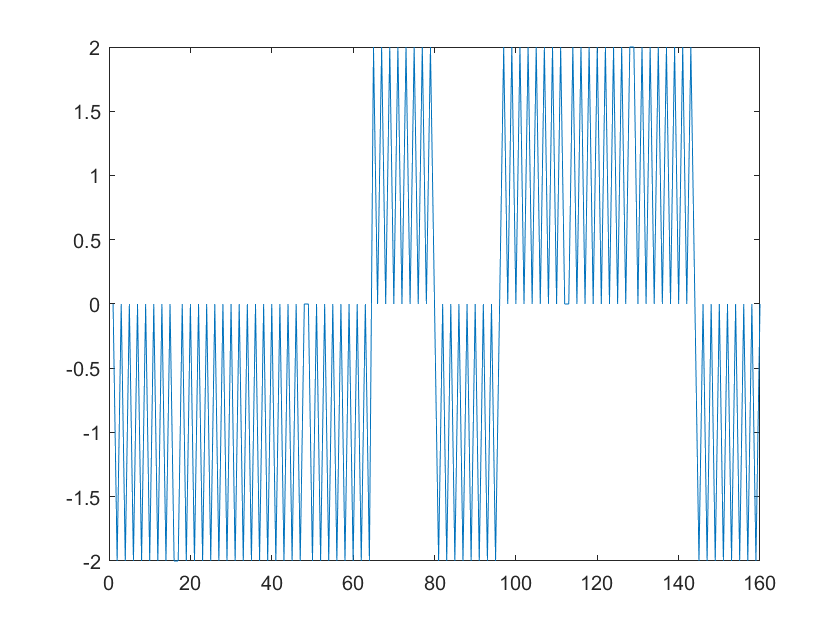

clear all
clc
n = 4;
H = WalshHamadard(n);

orth = dot(H(:,1), H(:,2));

user1 = randi([0,1], 1, 10);
user2 = randi([0,1], 1, 10);

user1(user1==0) = -1;
user2(user2==0) = -1;

code1 = H(:,1)';
code2 = H(:,2)';
cdma = [];
bound = 1;
%zeros(10,16)
for i = 1:10
    cdma(bound:bound+15) = user1(i)*code1 + user2(i)*code2;
    bound = bound+16;
end
plot(cdma);

Part 2

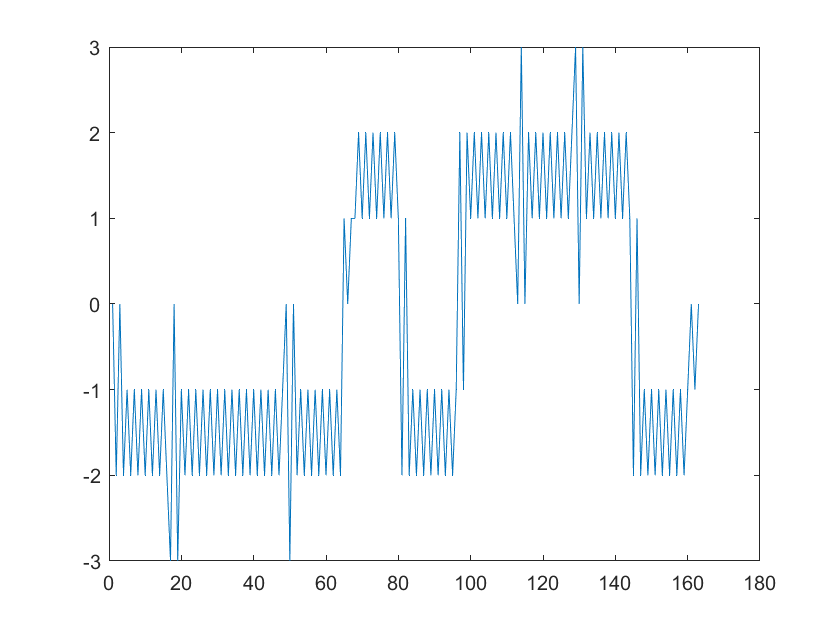

cdma2 = [cdma zeros(1,3)];
xCDMA_m2 = circshift(cdma2, 3);
xCDMA_m = cdma2 + 0.5*xCDMA_m2;
plot(xCDMA_m);


rx_user1 = [];
rx_user2 = [];
bound = 1;
for i = 1:length(user1)
    rx_user1(i) = sum((xCDMA_m(bound:bound+15) .* code1) + (0.5*xCDMA_m(bound+2:bound+17) .* code1));
    rx_user2(i) = sum((xCDMA_m(bound:bound+15) .* code2) + (0.5*xCDMA_m(bound+2:bound+17) .* code2));
    bound = bound+16;
end

rx1 = sign(rx_user1);
rx2 = sign(rx_user2);



Part 3

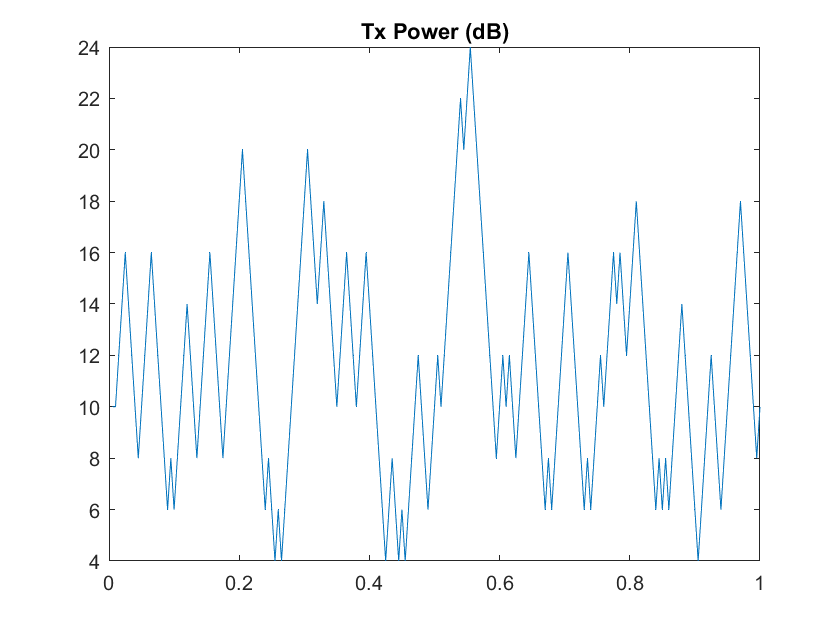

[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.4e9, 2, 5e-3);
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate))); title('Tx Power (dB)');

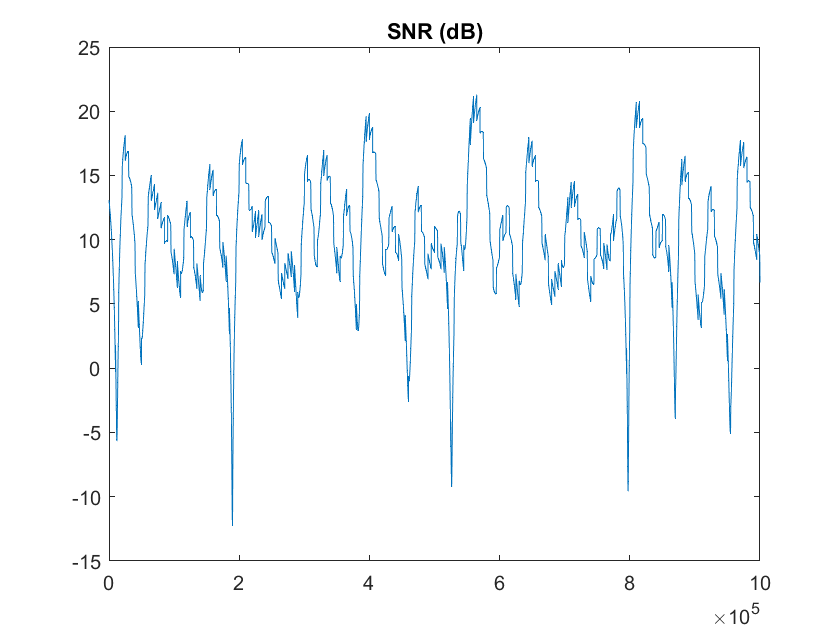

figure;
plot(SNRdB); title('SNR (dB)');

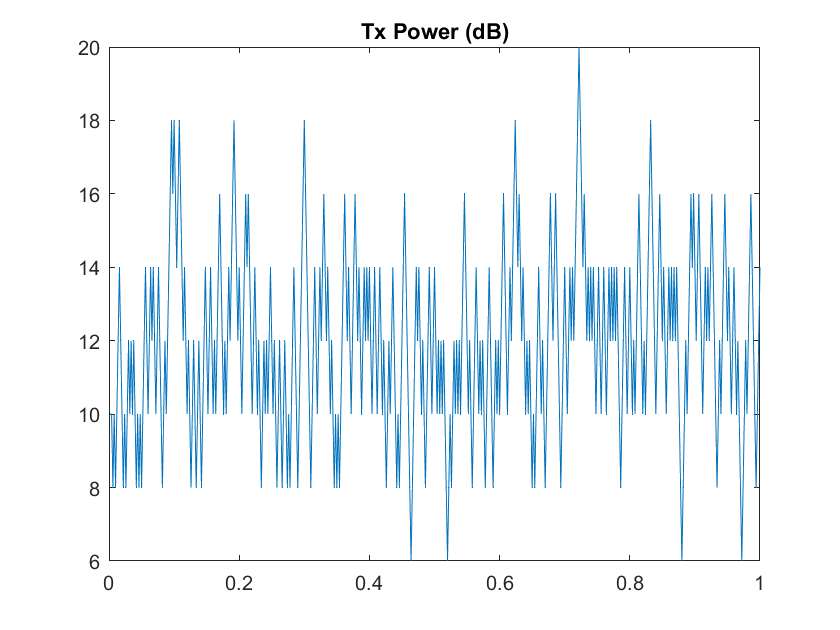

[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.1e9, 83, 2e-3); %Kawasaki Ninja H2 using 3G
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate))); title('Tx Power (dB)');

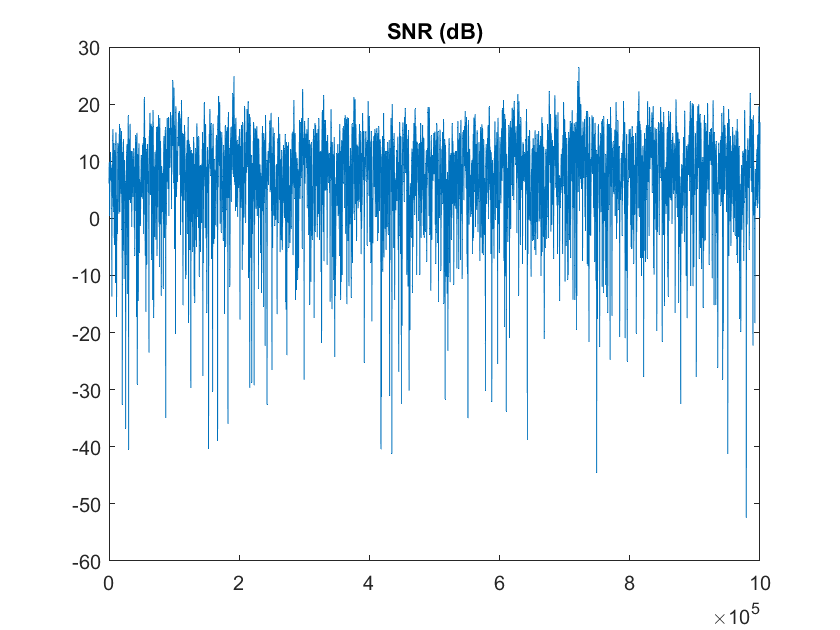

figure;
plot(SNRdB); title('SNR (dB)');

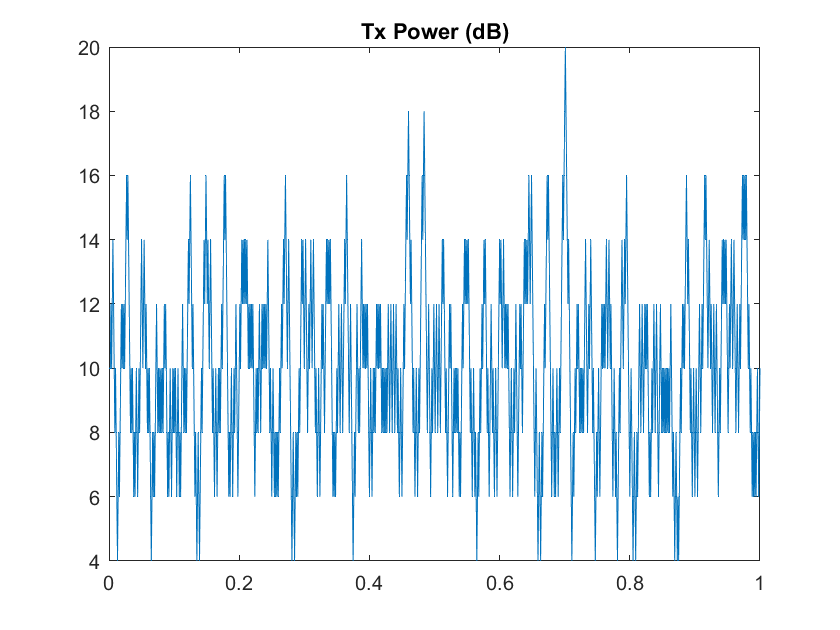

[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(6e9, 99, 1e-3); %Lamborghini Countach using 5G
figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate))); title('Tx Power (dB)');

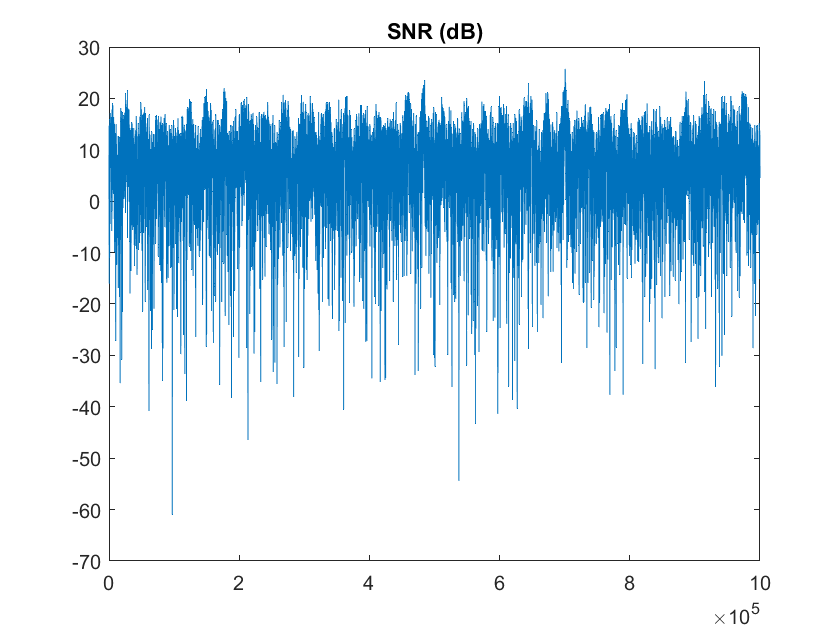

figure;
plot(SNRdB); title('SNR (dB)');